**Data**

x = [3 4 5 7 8 9 11 12]';

y = [40 88 110 200 290 347 510 625]';

**Plot data**

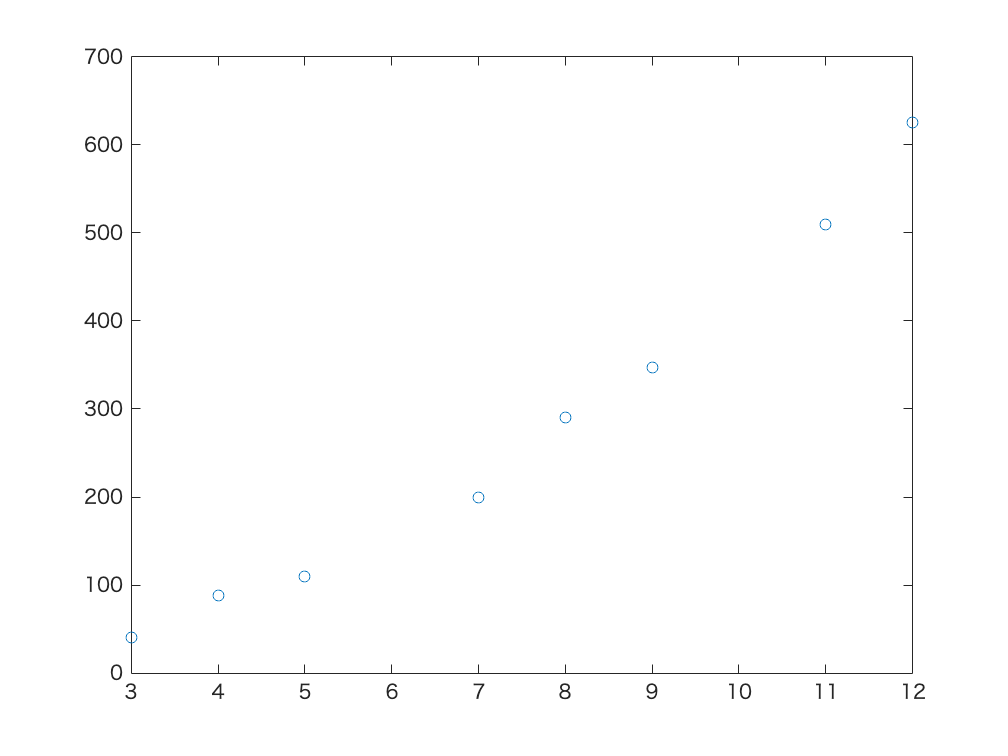

plot(x, y, 'o')

**Create Z matrix**

Z = [ones(size(y)), x, x.^2]

Z =      1     3     9
     1     4    16
     1     5    25
     1     7    49
     1     8    64
     1     9    81
     1    11   121
     1    12   144


**Solve for unknown parameters  a **

$\left\lbrack {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrack \mathit{\mathbf{Z}}\right\rbrack \right\rbrack \left\lbrace a\right\rbrace =\left\lbrace {\left\lbrack \mathit{\mathbf{Z}}\right\rbrack }^{\mathit{\mathbf{T}}} \left\lbrace \mathit{\mathbf{y}}\right\rbrace \right\rbrace$*(see as ****A****x = ****b****, in MATLAB as x*` = A \ b`*)*

a = (Z' * Z) \ (Z' * y)

a =     0.0024    0.0229    0.2322


**Plot data and the best fitted curve**

xp = linspace(min(x), max(x), 100)

xp =     3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545    5.5455    5.6364    5.7273    5.8182    5.9091    6.0000    6.0909    6.1818    6.2727    6.3636    6.4545    6.5455    6.6364    6.7273    6.8182    6.9091    7.0000    7.0909    7.1818    7.2727    7.3636    7.4545


yp = a(1) + (a(2) .* xp) + (a(3) .* xp.^2)

yp =     2.1611    2.2918    2.4263    2.5646    2.7068    2.8529    3.0027    3.1564    3.3140    3.4754    3.6406    3.8096    3.9825    4.1593    4.3398    4.5243    4.7125    4.9046    5.1005    5.3003    5.5039    5.7113    5.9226    6.1378    6.3567    6.5795    6.8062    7.0366    7.2709    7.5091    7.7511    7.9969    8.2466    8.5001    8.7574    9.0186    9.2837    9.5525    9.8252   10.1018   10.3821   10.6664   10.9544   11.2463   11.5420   11.8416   12.1450   12.4523   12.7634   13.0783


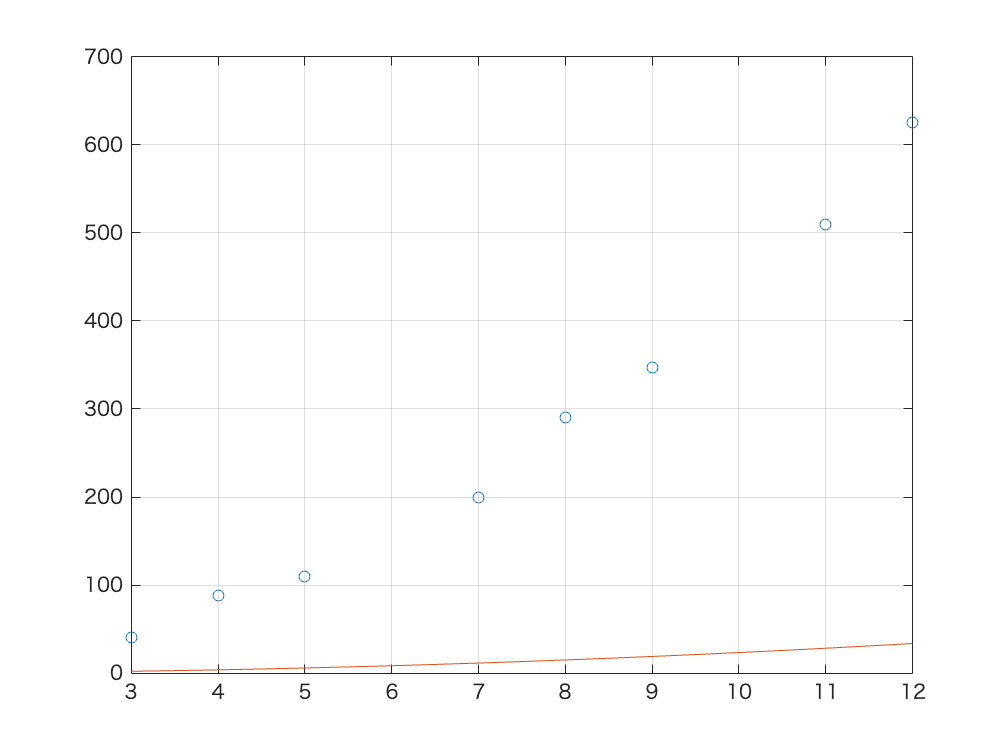

plot(x, y, 'o', xp, yp)
grid on

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

sr = sum((y - (Z*a)) .^ 2)

sr = 1.0e+05 *

    9.1667    9.1572    8.2055


**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

st = sum((y - mean(y)).^2)

st = 3.0617e+05

**Compute  r2  (the coefficient of determination)**

r2 = 1 - (sr/st)

r2 =    -1.9940   -1.9909   -1.6801


**Compute  syx  (the standard error of the estimate)  **

syx = sqrt(sr / (length(y) - length(p)))

関数または変数 'p' が認識されません。

**Predict the value of y for the given x**

xtest = 6
ytest = a(1) + (a(2) .* xtest) + (a(3) .* xtest.^2)